# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 16-Jul-2019 12:52:49

## Create the Layer Graph

Create the layer graph variable to contain the network's layers.

lgraph = layerGraph();

## Add the Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.


inputSize = [5 9 2];
filterSize = [2 2 2];
classes = 2;
numHiddenUnits =128;
miniBatchSize =10;
CNNFilterSize=[2,2];


tempLayers = [
    sequenceInputLayer([5 9 2],"Name","InputNIRS","Normalization","zerocenter")
    sequenceFoldingLayer("Name","Fold")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer(2,96,"Name","ConvA2d")
    maxPooling2dLayer(2,"Name","maxpoolA2d")
    convolution2dLayer(2,96,"Name","ConvB2d")
    maxPooling2dLayer(2,"Name","maxpoolB2d")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    sequenceUnfoldingLayer("Name","Unfold")
    flattenLayer("Name","flattenForLSTM")
    lstmLayer(128,"Name","LSTM","OutputMode","last")
    fullyConnectedLayer(2,"Name","DenseFCALayer")
    dropoutLayer(0.25,"Name","DenseDropoutLayer")
    fullyConnectedLayer(2,"Name","DenseFCBLayer")
    softmaxLayer("Name","softmaxLayer")
    classificationLayer("Name","BinaryClassifier")];
lgraph = addLayers(lgraph,tempLayers);

## Connect the Layer Branches

Connect all the branches of the network to create the network's graph.

lgraph = connectLayers(lgraph,"Fold/out","ConvA2d");
lgraph = connectLayers(lgraph,"Fold/miniBatchSize","Unfold/miniBatchSize");
lgraph = connectLayers(lgraph,"maxpoolB2d","Unfold/in");

## Clean Up Helper Variable

clear tempLayers;

## Plot the Layers

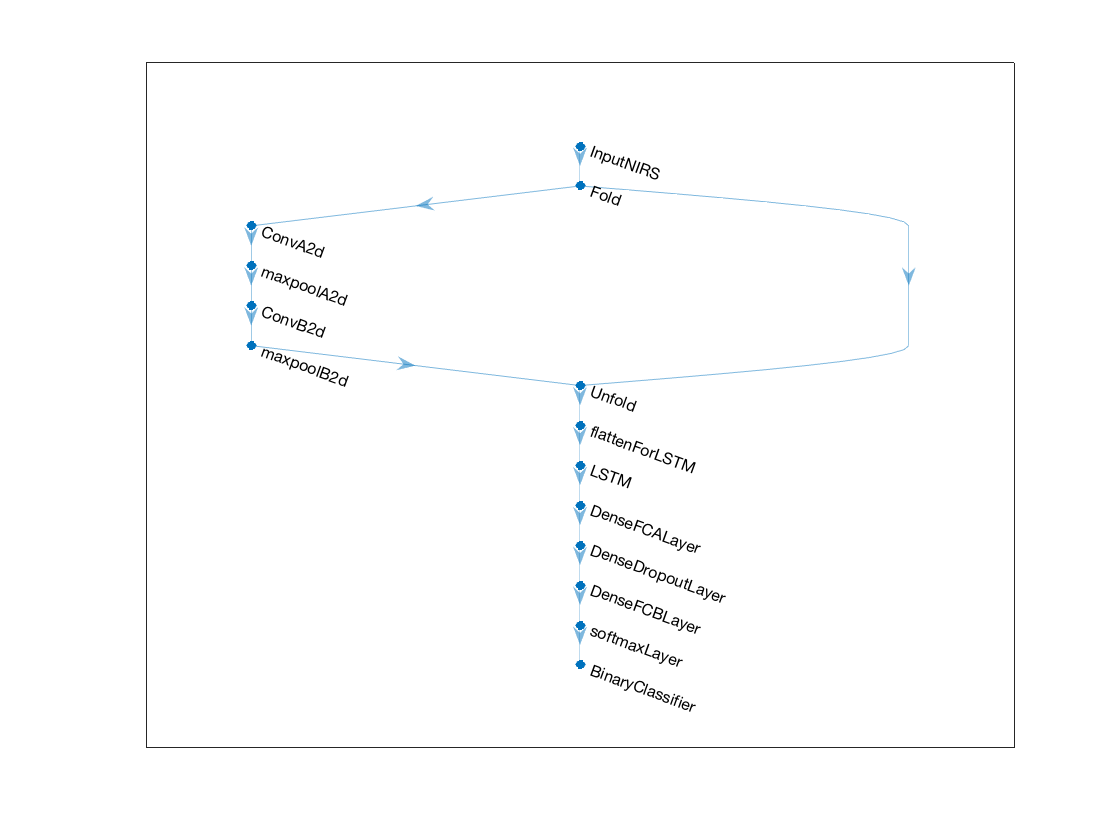

plot(lgraph);